## Anaylsis of Indirect Band Gap (GaP)

% Load As data


V0_1 = smooth(V0);
V0abs = abs(V0_1);
V1_1 = smooth(V1);
V1_1offset = max(V1_1);
negV1_1 = V1_1 - V1_1offset;
V1abs = abs(negV1_1);

% y1; % actually x
% x1; % actually y


T = V1abs./V0abs;
% R = (3.5860 - 1)^2 / (3.5860 + 1)^2
 R = 0.33

R = 0.3300

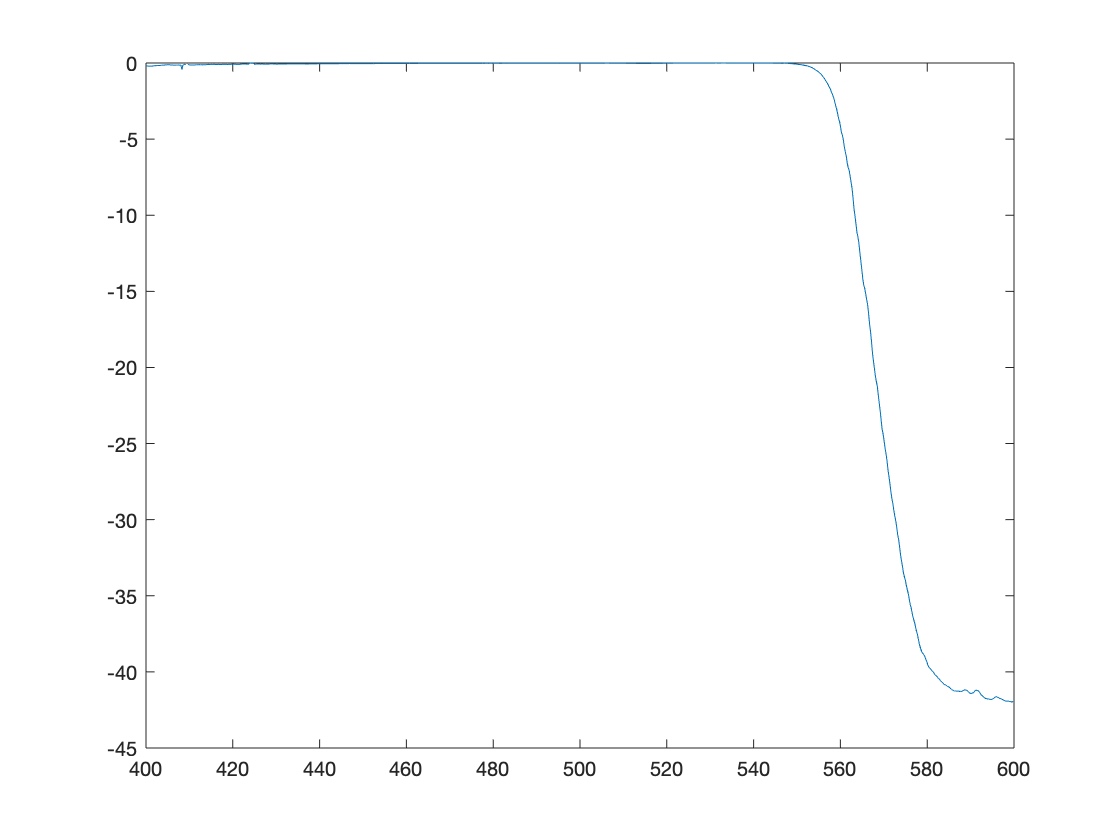


x = 0.32.*10.^(-2); % error = 0.001 %actually 0.417.*10.^(-3)
h = 6.62607004*10^(-34) ;
c = 299792458;

alpha = -(x.^(-1)).*log((((1 - R).^4 + 4.*(T.^2).*(R.^2)).^0.5 - (1 - R).^2)./(2.*T.*(R.^2)));

offsetalpha = alpha + abs(-500.2303);

squarealpha = offsetalpha.^2;

square_alpha = smooth(squarealpha);

%sqrtalpha = sqrt(abs(alpha));

%sqrtalpha = smooth(sqrtalpha);

alpha_check =  (1/x).*log(((1-R).^2)./T);

a = alpha_check - alpha;
plot(wavelength,a)

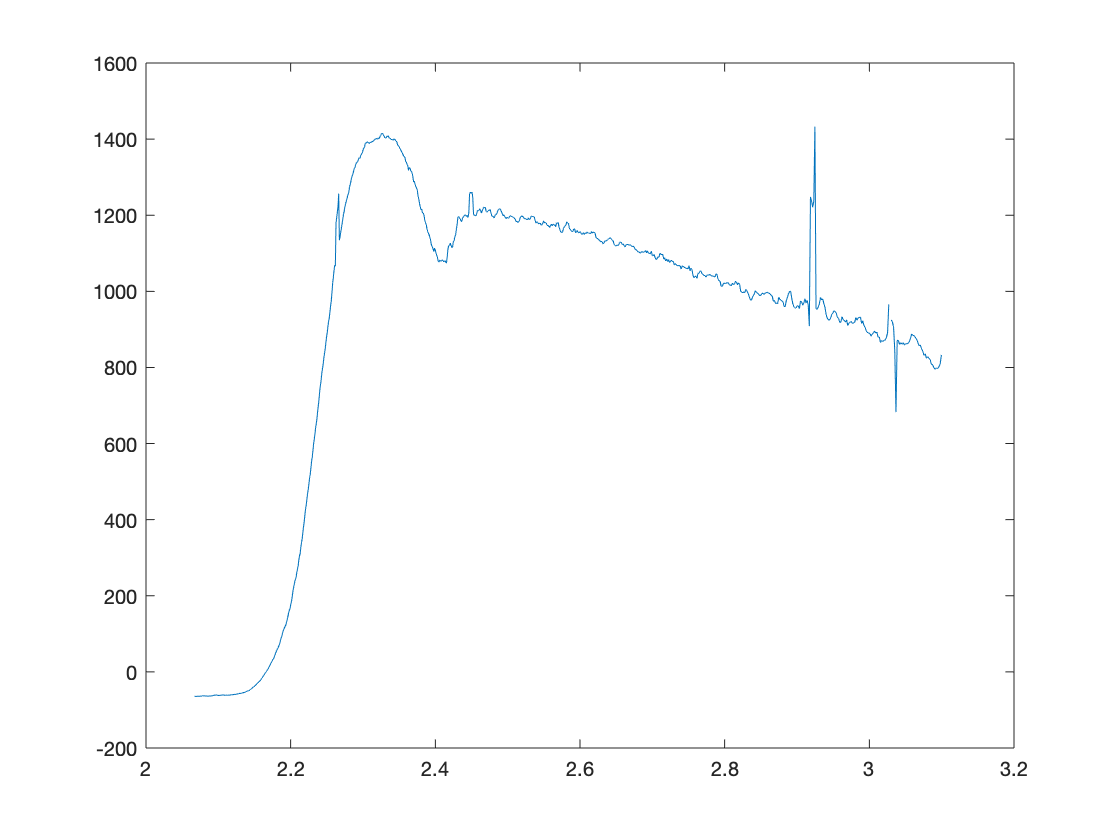


plot(eV_energy,alpha_check)


Joules_energy = (h*c)./(wavelength.*10.^(-9));
eV_energy = Joules_energy./(1.602176634*10^(-19));

Log_alpha_GaAs = log10(offsetalpha)

Log_alpha_GaAs =     3.1249
    3.1169
    3.1146
    3.1132
    3.1137
    3.1124
    3.1138
    3.1164
    3.1169
    3.1210


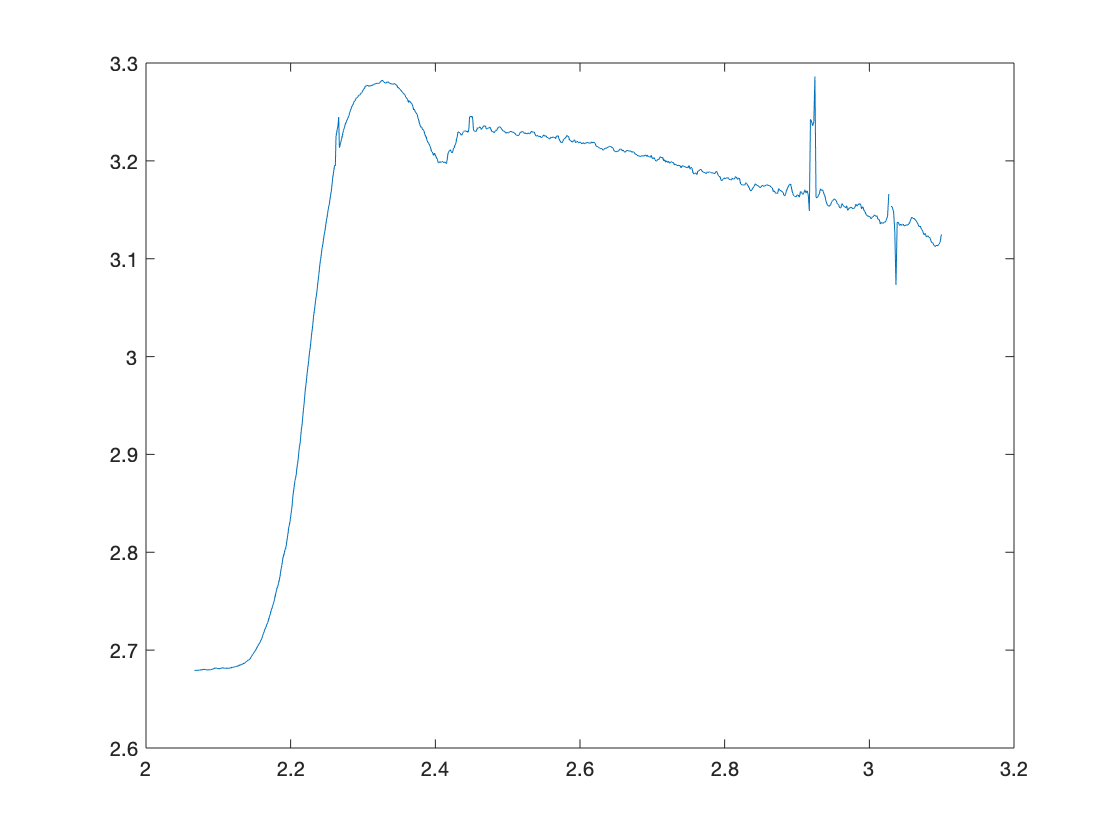


plot(eV_energy,Log_alpha_GaAs)

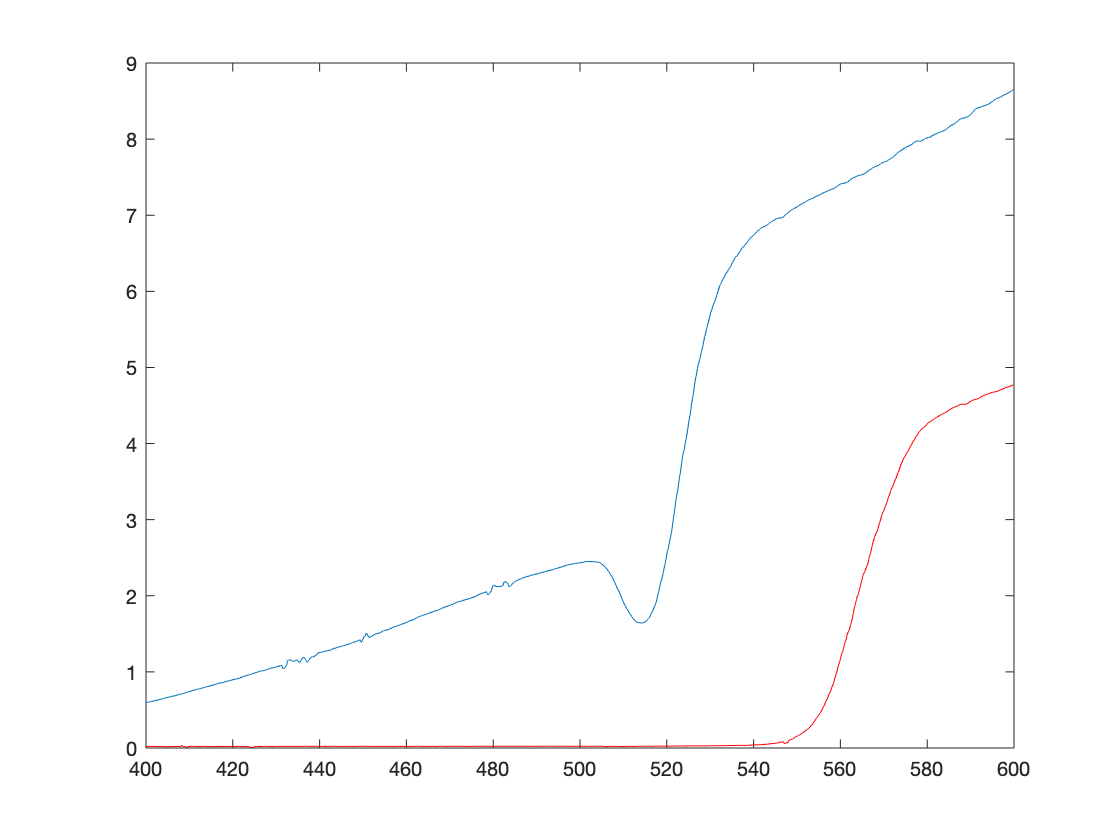


plot(wavelength,V0abs)
hold on
plot(wavelength,V1abs,'r')
hold off

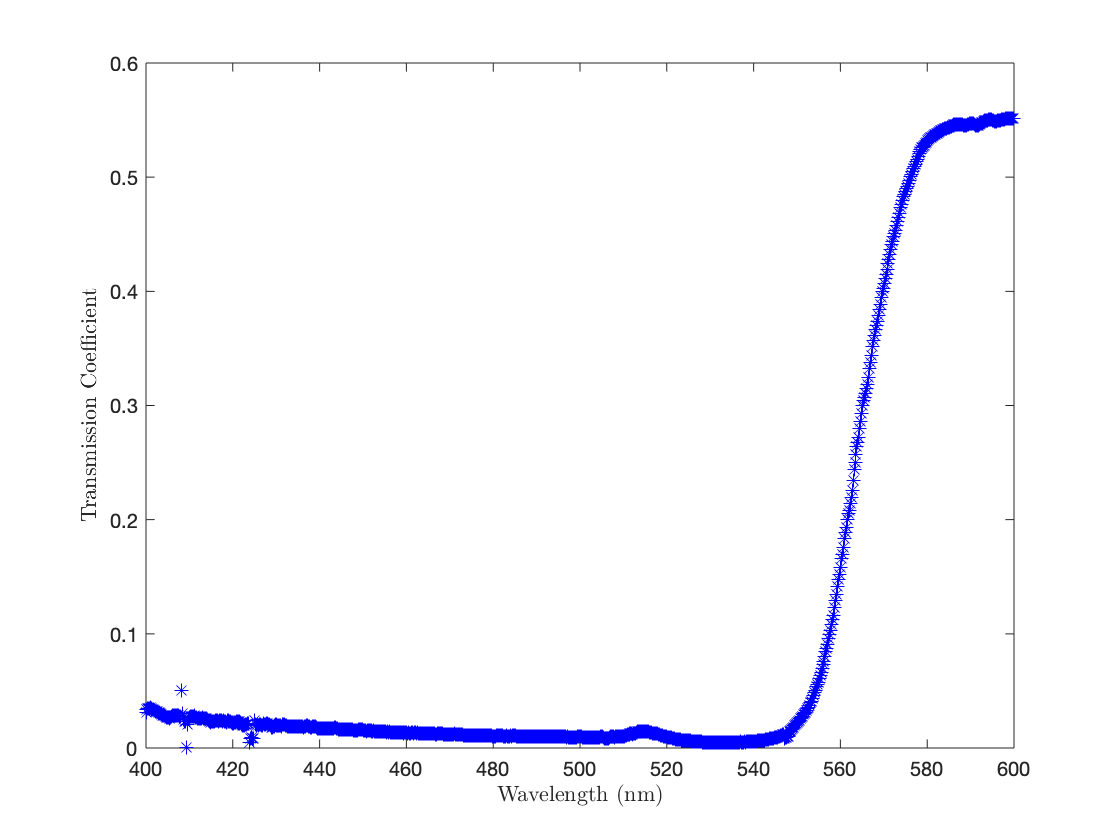



figure(1)
plot(wavelength,T,'b*')
xlabel('Wavelength (nm)','Interpreter','latex')
ylabel('Transmission Coefficient','Interpreter','latex')
hold on
% plot(fittedmodel)
% plot(y1,x1,'b-')

hold off

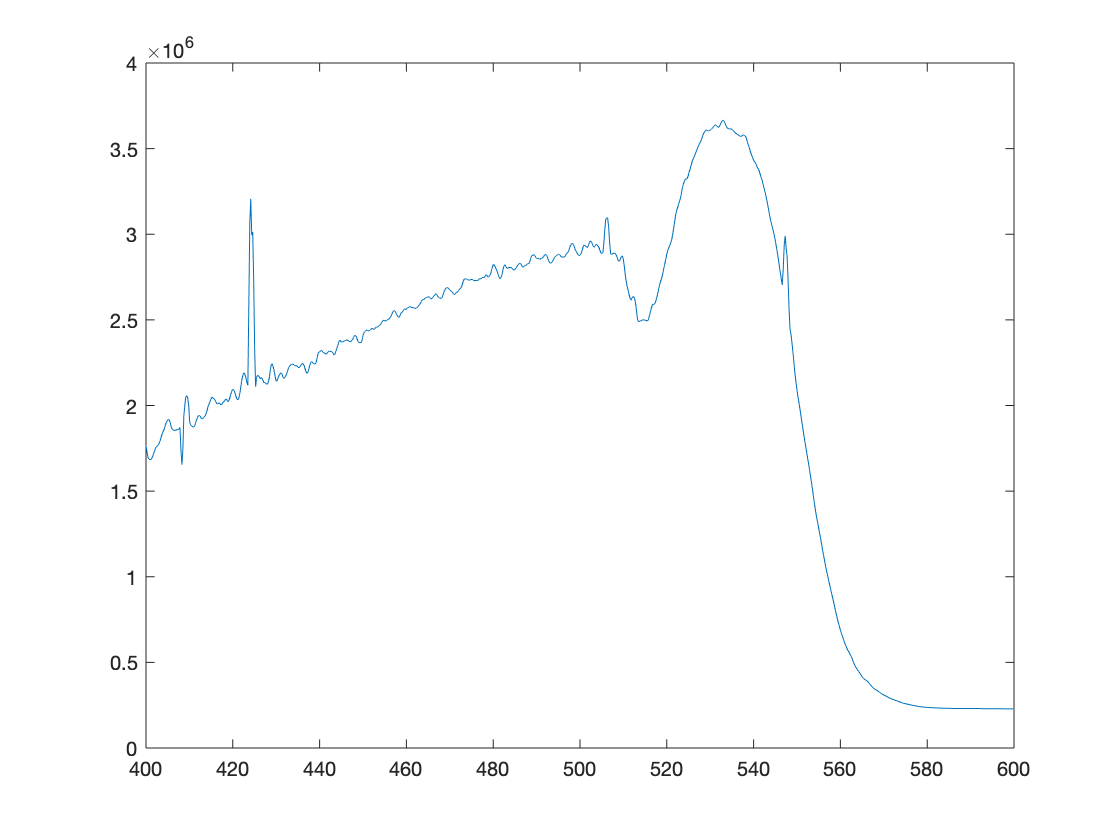


figure(2)
plot(wavelength,V1abs,'b-')
hold on
plot(wavelength,V0abs,'r-')
xlabel('Wavelength (nm)','Interpreter','latex')
ylabel('Voltage','Interpreter','latex')

hold off

figure(3)
plot(wavelength,alpha)

hold off

figure(4)
plot(wavelength,square_alpha)

hold off

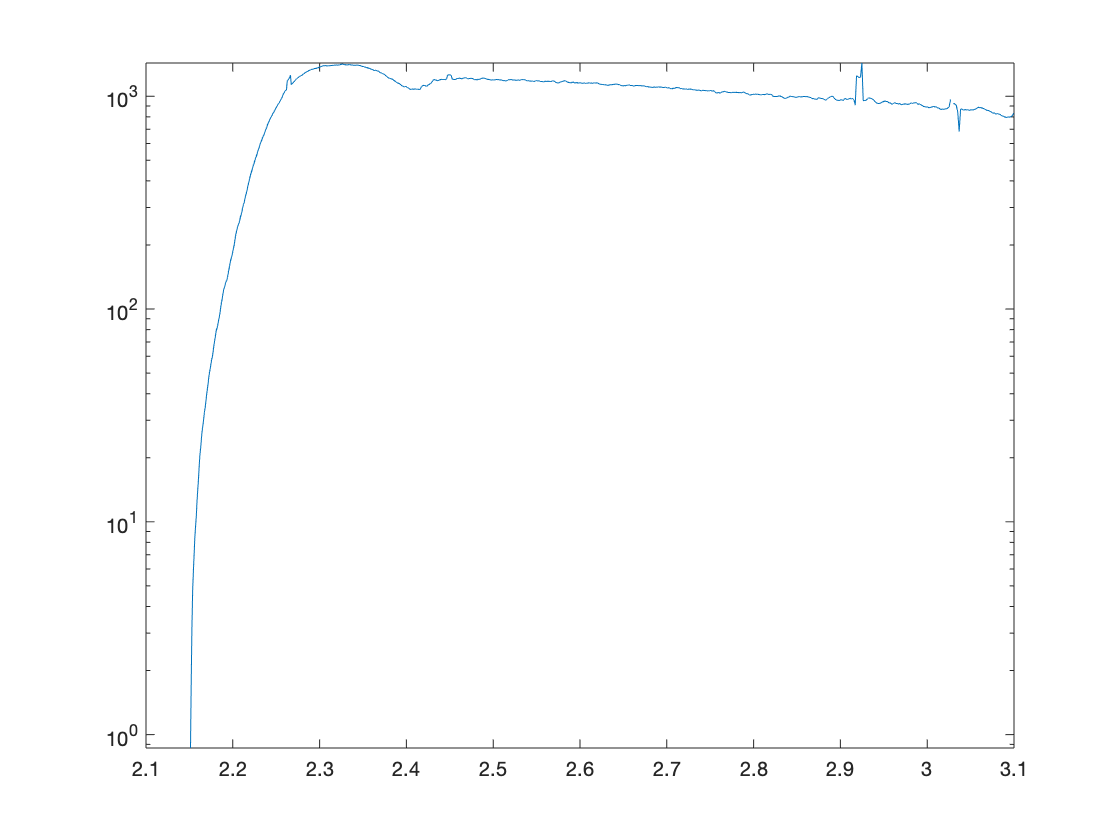


figure(5)
plot(eV_energy,alpha)
set(gca, 'YScale', 'log')

hold off

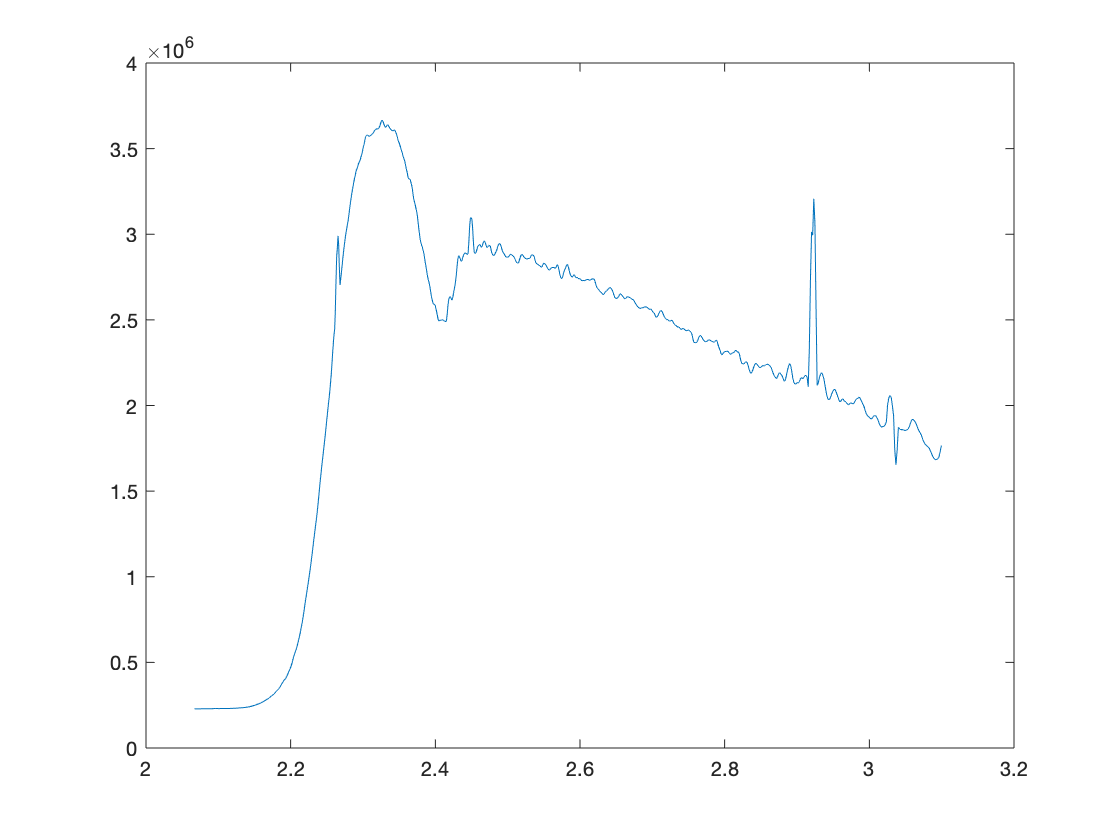


figure(6)
plot(eV_energy,square_alpha)